load('square_101.mat');
% data2 = load('square_102.mat');
% theta = merge(data1.theta, data2.theta);

delay_estimate = 100;
initial_condition = [0; 0; 0;];

theta_offset = theta(1);
I_corrected = I_mot(delay_estimate+1:end);
theta_corrected = theta(delay_estimate+1:end) -  theta_offset;
phidot_corrected = phidot(delay_estimate+1:end);
u_real = u(delay_estimate+1:end);
theta_cal = theta_corrected*2*pi/4.5;

Ts = 0.01;
theta_dot = gradient(theta_cal, Ts);
y = [theta_cal, phidot_corrected];
% u = I_corrected;                          

% N = length(u);
% split_point = floor(2 * N / 3);  
% 
% u_train = u(1:split_point);
% y_train = y(1:split_point, :);
% 
% u_val = u(split_point+1:end);
% y_val = y(split_point+1:end, :);

data_id = iddata(y_train, u_train, 'Ts', 0.01);
Ts = 0.01;
opt = greyestOptions;
opt.InitialState =  initial_condition;


params_lin_init = {'J_theta', 0.3; 'mu_theta', 0.53; 'J_phi', 0.00292; 'mu_phi', 0.007535;
    'kt', 0.09648; 'mgL', 1.353};


linear_model = idgrey('linear_reaction_pendulum', params_lin_init, 'c');
linear_model.Structure.Parameters(1).Free = false;
% linear_model.Structure.Parameters(8).Free = false;
sys = greyest (data_id, linear_model, opt)

sys =
  Continuous-time linear grey box model defined by "linear_reaction_pendulum" function:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
             x1        x2        x3
   x1         0         0         1
   x2         0   -0.2466    0.2466
   x3    -11.45  0.002676   -0.8262
 
  B = 
           u1
   x1       0
   x2   188.6
   x3  -2.046
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
  K = 
       y1  y2
   x1   0   0
   x2   0   0
   x3   0   0
 
  Model parameters:
   J_theta = 0.3
   mu_theta = 0.2471
   J_phi = 0.003255
   mu_phi = 0.0008027
   kt = 0.6139
   mgL = 3.436
 
Parameterization:
   ODE Function: linear_reaction_pendulum
   Disturbance component: none
   Initial state: fixed to double value
   Number of free coefficients: 5
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using GREYEST

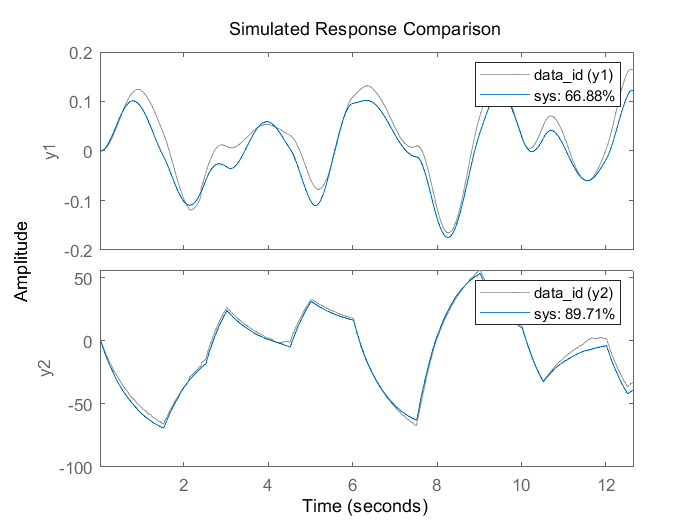


optcom = compareOptions;
optcom.InitialCondition = initial_condition;



compare(data_id,sys, optcom)

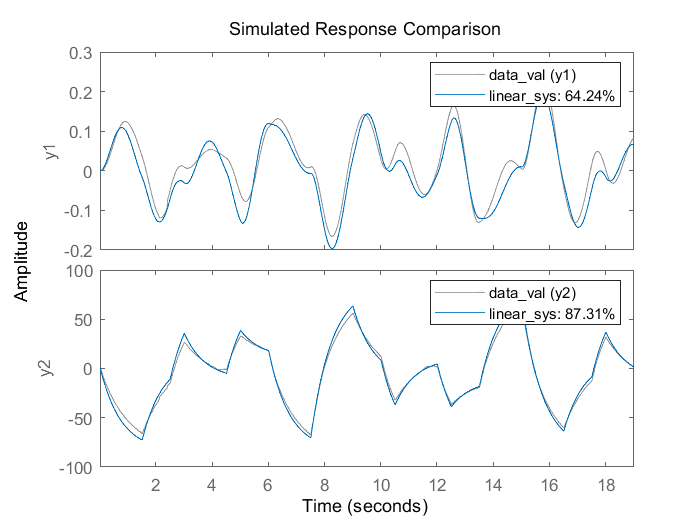

optval = compareOptions;
initial_condition = [0; 0; 0; 0];
optval.InitialCondition = initial_condition;
% initial_condition;
% [y_val(1,1); y_val(1,2); -0.25];

data_val = iddata(y, u_real, 'Ts', 0.01);
compare(data_val, linear_sys, optval)

Order = [2 1 3];   % [#outputs, #inputs, #states]
Ts = 0.01;              
kt = 0.6139;
mu_phi = 0.0008027;
mu_theta = 0.2471;
J_phi = 0.0032;
J_theta = 0.3;
mgL = 3.436;

% params_lin_init = {'J_theta', 0.89; 'mu_theta', 0.33; 'J_phi', 0.00492; 'mu_phi', 0.007535;
%     'kt', -0.9648; 'mgL', 1.353};


% 
% parameters    = {J_theta, mu_theta, J_phi, mu_phi, kt, mgL};
% 
% initial_states = initial_condition;
% nlgr = idnlgrey('reaction_pendulum_model', Order, parameters, initial_states, Ts);
% nlgr = setpar(nlgr,'Minimum',{eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) });
% nlgr = setpar(nlgr,'Fixed',{true true true true true true});
% data = iddata(y_train, u_train, 'Ts', 0.01);
% 
% % % nlgr.SimulationOptions.Solver = 'ode23';
% % 
% % % nlgr.Parameters(1).Fixed = true;
% % % nlgr.Parameters(4).Fixed = true;
% % % nlgr.Parameters(5).Fixed = true;
% % 
% % opt = nlgreyestOptions;
% % opt.Display = 'on';
% % %opt.SearchMethod = 'lsqnonlin';  
% % opt.SearchOptions.MaxIterations = 200;
% % 
% % estimated_model = nlgreyest(data, nlgr,'Display','Full')
% % 
% % getpvec(estimated_model)
tspan = (0:length(u_train)-1) * Ts;
u_interp = @(t) interp1(tspan, u_train, t, 'linear', 'extrap');
odefun = @(t, x) reaction_pendulum_model(t, x, u_interp(t), ...
    J_theta, mu_theta, J_phi, mu_phi, kt, mgL);
x0 = [0; 0; 0];  
[t_out, x_out] = ode45(odefun, tspan, x0);
y_sim = x_out(:, [1 2]);  

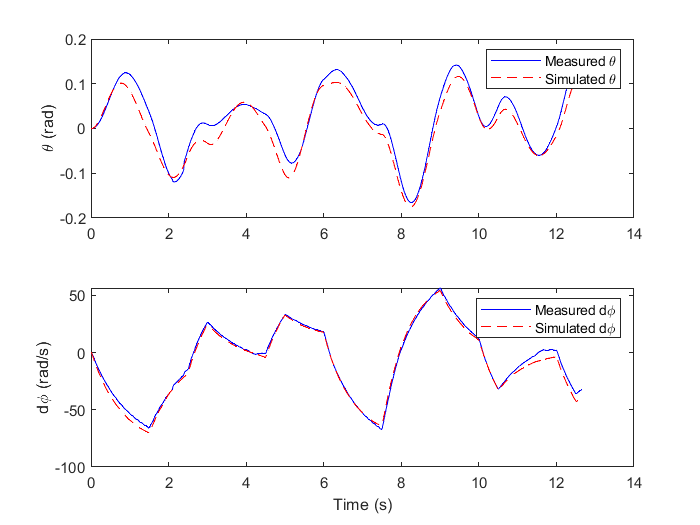

figure;
subplot(2,1,1);
plot(tspan, y_train(:,1), 'b', t_out, y_sim(:,1), 'r--');
legend('Measured \theta','Simulated \theta');
ylabel('\theta (rad)');

subplot(2,1,2);
plot(tspan, y_train(:,2), 'b', t_out, y_sim(:,2), 'r--');
legend('Measured d\phi','Simulated d\phi');
xlabel('Time (s)');
ylabel('d\phi (rad/s)');

vaf_theta = 100 * (1 - var(y_train(:,1) - y_sim(:,1)) / var(y_train(:,1)));
vaf_dphi  = 100 * (1 - var(y_train(:,2) - y_sim(:,2)) / var(y_train(:,2)));

fprintf('VAF (theta): %.2f%%\n', vaf_theta);

VAF (theta): 95.57%


fprintf('VAF (dphi) : %.2f%%\n', vaf_dphi);

VAF (dphi) : 99.28%





% figure;
% compare(data,reaction_pendulum_model,optcom)

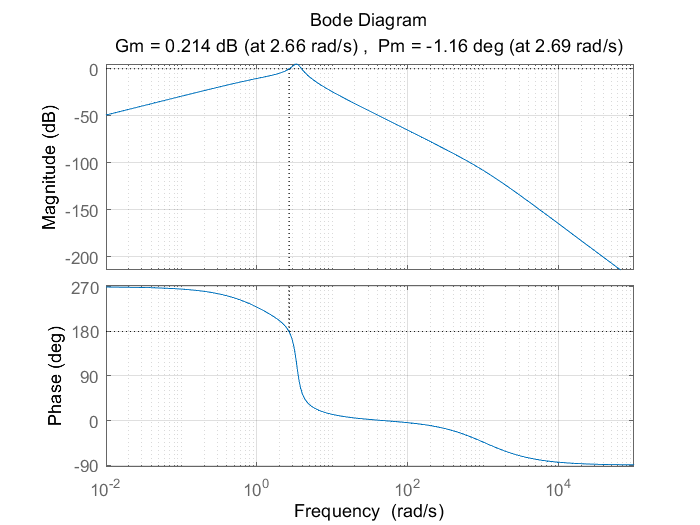

A = connected.A;
%A(3,1) = -A(3,1);
B = connected.B;
C = connected.C;
D = connected.D;
[num, den] = ss2tf(A, B, C, D, 1);
linear_sys = ss(A, B, C, D);
sys_min = minreal(linear_sys);
siso_sys = sys_min(1, 1);


figure;
margin(siso_sys);
grid on;

[mag, phase, omega] = bode(siso_sys);
mag = squeeze(mag); 
omega = squeeze(omega); 
mag_db = 20*log10(mag); 
index_3db = find(mag_db <= -3, 1, 'first'); 
bw = omega(index_3db);
disp(['Bandwidth: ', num2str(bw), ' rad/s']);

Bandwidth: 0.01 rad/s


% figure;
% step(siso_sys);
% title('Step Response');
% grid on;


Kp = 1; 
Ki = 0; 
Kd = 0; 
Tf = 1; 
pid_controller = Kp + tf([0 Ki], [1 0]) + tf([Kd 0], [Tf 1]);
open_loop = pid_controller * siso_sys;
closed_loop = feedback(open_loop, 1);

[GM, PM, Wcg, Wcp] = margin(open_loop);
disp(['Gain Margin (dB): ', num2str(20*log10(GM))]);

Gain Margin (dB): 0.2137


disp(['Phase Margin (degrees): ', num2str(PM)]);

Phase Margin (degrees): -1.1604


disp(['Gain Crossover Frequency (rad/s): ', num2str(Wcg)]);

Gain Crossover Frequency (rad/s): 2.6625


disp(['Phase Crossover Frequency (rad/s): ', num2str(Wcp)]);

Phase Crossover Frequency (rad/s): 2.6875



[mag, ~, omega] = bode(open_loop);
mag = squeeze(mag);
omega = squeeze(omega);
mag_db = 20*log10(mag);
index_bw = find(mag_db <= -3, 1, 'first'); 
bw = omega(index_bw);
disp(['Bandwidth: ', num2str(bw), ' rad/s']);

Bandwidth: 0.01 rad/s


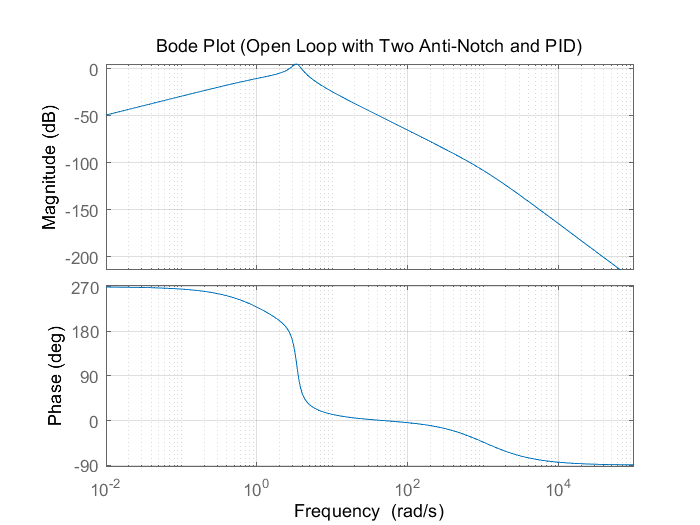


figure;
bode(open_loop);
grid on;
title('Bode Plot (Open Loop with Two Anti-Notch and PID)');

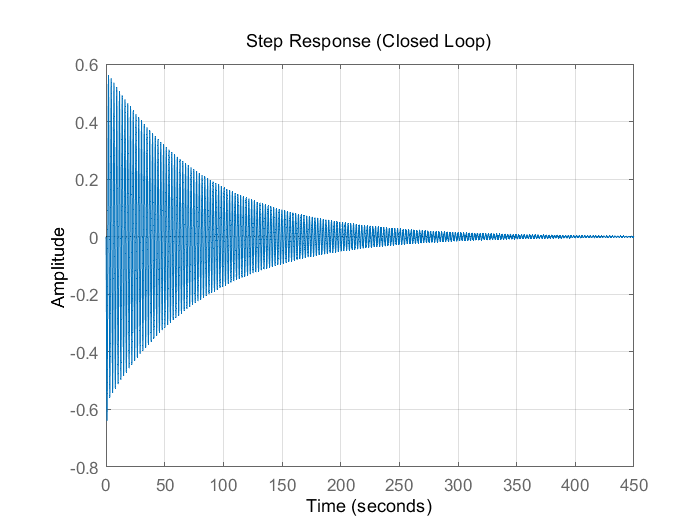


figure;
step(closed_loop);
grid on;
title('Step Response (Closed Loop)');

Q = 1e-4 * eye(4);   
R = 1e-2 * eye(2);   
G = eye(4);
[L, P, E] = dlqe(A, G, C, Q, R);
sys_est = ss(A - L*C, [B L], C, 0, -1); 
N = length(y);
xhat = zeros(4, N); 
xhat(:,1) = zeros(4,1);
for k = 1:N-1
    xhat(:,k+1) = A * xhat(:,k) + B * u_real(k,:)' + L * (y(k,:)' - C * xhat(:,k));
end
